# Clustering & Classification

**Evaluation: Macro F1 Score and Accuracy**

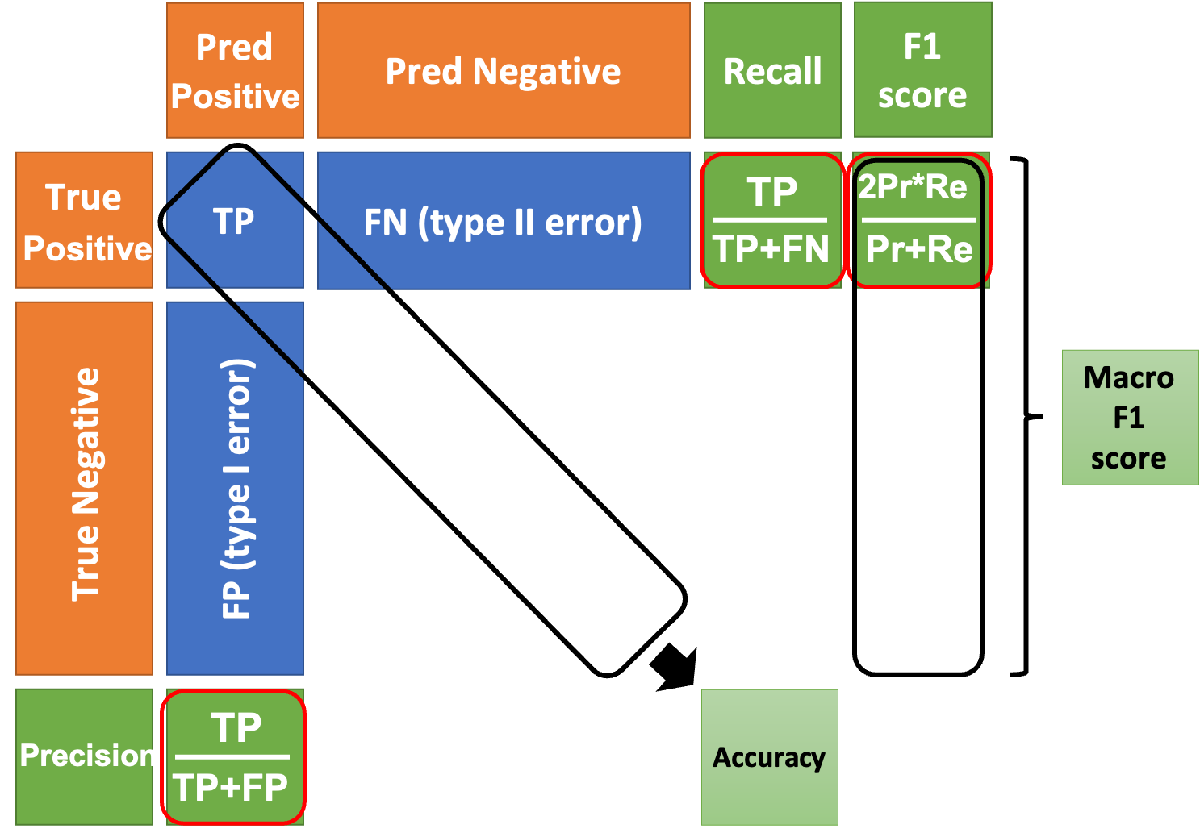

## K-means (Spectral clustering)

**K-means is a unsupervised learning.**

- The database contains 150 iris flower infomation. Each data has 4 information, sepal length, sepal width, petal length and petal width.

- There are 3 classes, Setosa, Versicolour and Virginica. Each class contains 50 data.

clc; clear; close all;
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
% load fisheriris
load("irismat.mat")
bandwidth = 2.5;
num_eigvec = 3;
fix_random_seed = true;
if fix_random_seed
    rng(1); % For reproducibility
end
[U, S] = DMapBasic(meas, 100, num_eigvec, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 99.
(info) The first 10% number of points in bandwidth neighborhood is 85.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


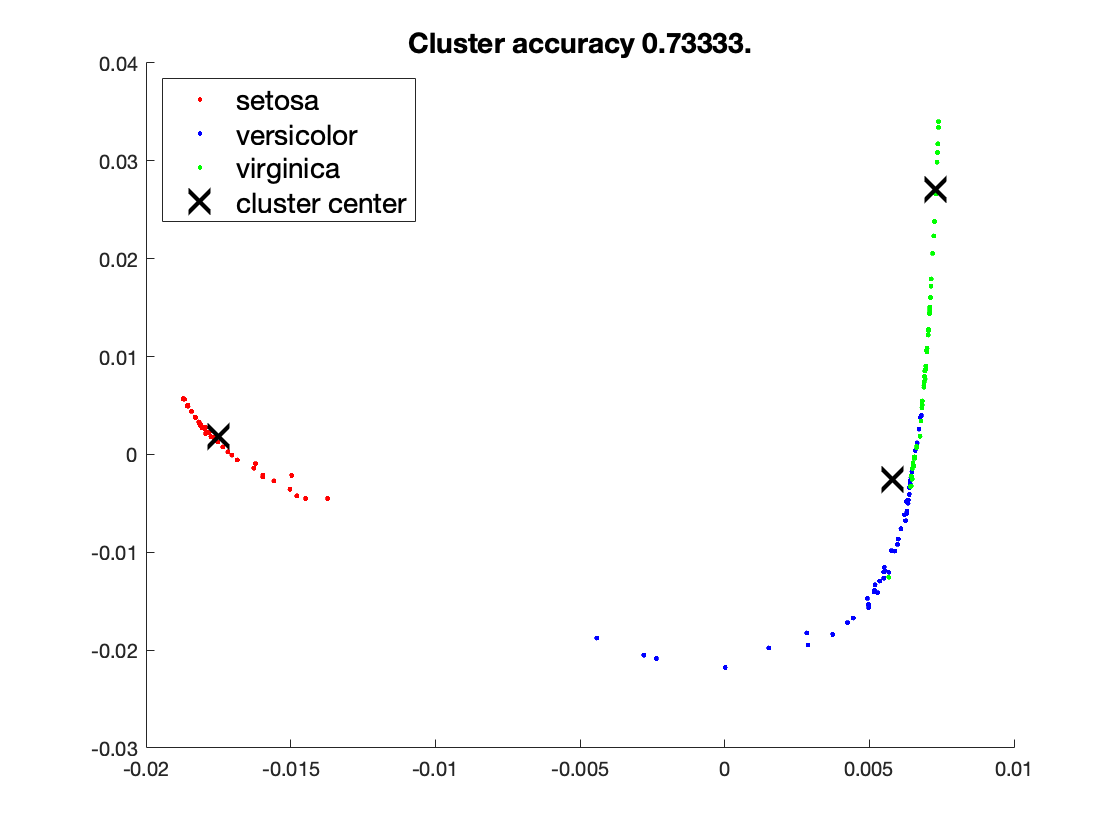

[class_idx, class_center] = kmeans(U,3);
acc = cluster_acc(species, class_idx);

figure
hold on
plot(U(species==1, 1), U(species==1, 2), 'r.')
plot(U(species==2, 1), U(species==2, 2), 'b.')
plot(U(species==3, 1), U(species==3, 2), 'g.')
plot(class_center(:, 1), class_center(:, 2), 'kx', 'MarkerSize', 15, 'LineWidth',3)
legend({'setosa', 'versicolor', 'virginica', 'cluster center'}, 'Location','northwest', 'FontSize', 14)
title(['Cluster accuracy ', num2str(acc), '.'], 'FontSize', 14)
hold off

## Support vector machine

**SVM is a supervised learning.**

clc; clear; close all;
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
% load fisheriris
load("irismat.mat")
X = meas;
Y = species;
n = size(X, 1);
Y_hot = zeros(n, 3);
for i = 1:3
    Y_hot(Y==i, i) = 1;
end

### Evaluation on ONE validation set

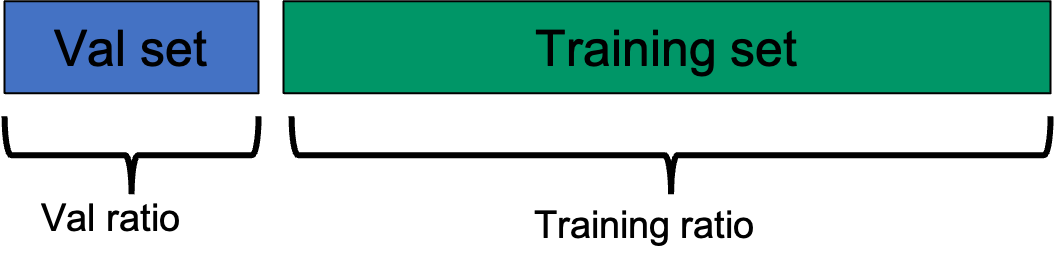

% split train and validation set
train_ratio = 0.8;
[train_idx, val_idx] = Split_Set(n, train_ratio);

% SVM
template = templateSVM('KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], 'KernelScale', 10, ...
    'BoxConstraint', 1, 'Standardize', true);

model = fitcecoc(X(train_idx, :), Y(train_idx, :), ...
    'Learners', template, ...
     'Coding', 'onevsone', ...
     'ClassNames', [1; 2; 3]);
 
[~, train_scores] = predict(model, X(train_idx, :));
[~, conf_mat] = confusion(Y_hot(train_idx, :)', train_scores');

acc = sum(diag(conf_mat)) / sum(conf_mat(:));
disp(['Training accuracy = ' num2str(acc)])

Training accuracy = 0.95868



[~, val_scores] = predict(model, X(val_idx, :));
[~, conf_mat] = confusion(Y_hot(val_idx, :)', val_scores');

[cell_info, ~, ~, ~] = CM2Info(conf_mat, {'seto', 'vers', 'virg'});
disp('The following is confusion matrix of validation set')

The following is confusion matrix of validation set


disp(cell_info)

    {0×0 double         }    {'Predict-seto'}    {'Predict-vers'}    {'Predict-virg'}    {'PR'      }    {'RE'      }    {'F1'      }
    {'Target-seto (45%)'}    {'13 (100%)'   }    {'0 (0%)'      }    {'0 (0%)'      }    {[       1]}    {[       1]}    {[       1]}
    {'Target-vers (24%)'}    {'0 (0%)'      }    {'7 (100%)'    }    {'0 (0%)'      }    {[  0.8750]}    {[       1]}    {[  0.9333]}
    {'Target-virg (31%)'}    {'0 (0%)'      }    {'1 (11%)'     }    {'8 (89%)'     }    {[       1]}    {[  0.8889]}    {[  0.9412]}
    {0×0 double         }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}
    {'Accuracy: 0.9655' }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}
    {'Macro F1: 0.9582' }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}



### Evaluation on cross validation by k-folds.

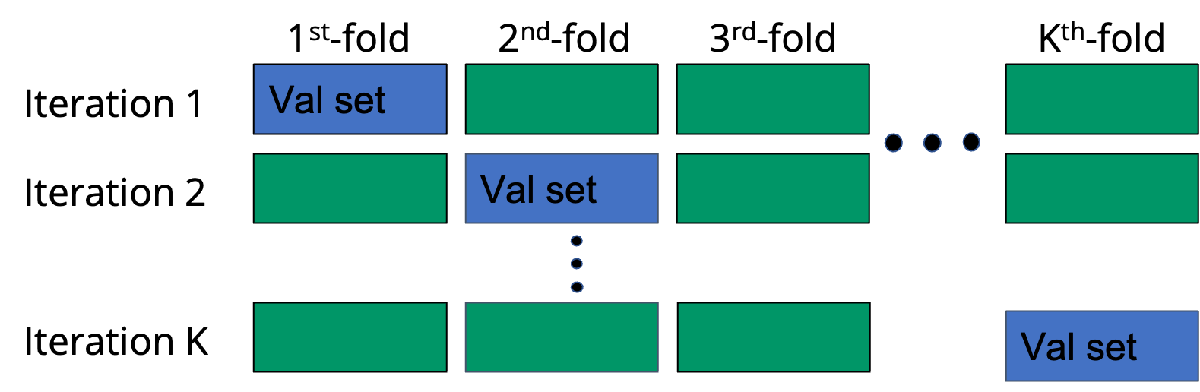

% split train and validation set
k_fold = 8;
[train_idices, val_idices] = Split_Set(n, k_fold);

% apply K-fold validation
val_accs = [];
val_f1s = [];
conf_mats = zeros(3); % sum over all validation confusion matrices
for i = 1:k_fold
    train_idx = train_idices{i};
    val_idx = val_idices{i};
    
    % SVM
    template = templateSVM('KernelFunction', 'gaussian', ...
        'PolynomialOrder', [], 'KernelScale', 10, ...
        'BoxConstraint', 1, 'Standardize', true);
    
    % train
    model = fitcecoc(X(train_idx, :), Y(train_idx, :), ...
        'Learners', template, ...
         'Coding', 'onevsone', ...
         'ClassNames', [1; 2; 3]);
    
    [~, train_scores] = predict(model, X(train_idx, :));
    [~, conf_mat] = confusion(Y_hot(train_idx, :)', train_scores');
    train_acc = sum(diag(conf_mat)) / sum(conf_mat(:));

    % evaluation
    [~, val_scores] = predict(model, X(val_idx, :));
    [~, conf_mat] = confusion(Y_hot(val_idx, :)', val_scores');
    [val_f1, val_acc] = CM2MacroF1(conf_mat);
    
    disp_str = sprintf('[ %d / %d ]: Training accuracy = %.3f, Validation accuracy = %.3f', i, k_fold, train_acc, val_acc);
    disp(disp_str)
    
    % store all info
    val_f1s = [val_f1s, val_f1];
    val_accs = [val_accs, val_acc];
    conf_mats = conf_mats+conf_mat;
end

[ 1 / 8 ]: Training accuracy = 0.947, Validation accuracy = 0.947
[ 2 / 8 ]: Training accuracy = 0.962, Validation accuracy = 0.842
[ 3 / 8 ]: Training accuracy = 0.954, Validation accuracy = 0.947
[ 4 / 8 ]: Training accuracy = 0.962, Validation accuracy = 0.947
[ 5 / 8 ]: Training accuracy = 0.969, Validation accuracy = 0.947
[ 6 / 8 ]: Training accuracy = 0.962, Validation accuracy = 1.000
[ 7 / 8 ]: Training accuracy = 0.962, Validation accuracy = 1.000
[ 8 / 8 ]: Training accuracy = 0.962, Validation accuracy = 1.000


[cell_info, ~, ~] = CM2Info(conf_mats, {'seto', 'vers', 'virg'});
disp('The following is confusion matrix of validation set')

The following is confusion matrix of validation set


disp(cell_info)

    {0×0 double         }    {'Predict-seto'}    {'Predict-vers'}    {'Predict-virg'}    {'PR'      }    {'RE'      }    {'F1'      }
    {'Target-seto (33%)'}    {'50 (100%)'   }    {'0 (0%)'      }    {'0 (0%)'      }    {[       1]}    {[       1]}    {[       1]}
    {'Target-vers (33%)'}    {'0 (0%)'      }    {'49 (98%)'    }    {'1 (2%)'      }    {[  0.8909]}    {[  0.9800]}    {[  0.9333]}
    {'Target-virg (33%)'}    {'0 (0%)'      }    {'6 (12%)'     }    {'44 (88%)'    }    {[  0.9778]}    {[  0.8800]}    {[  0.9263]}
    {0×0 double         }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}
    {'Accuracy: 0.9533' }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}
    {'Macro F1: 0.9532' }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}



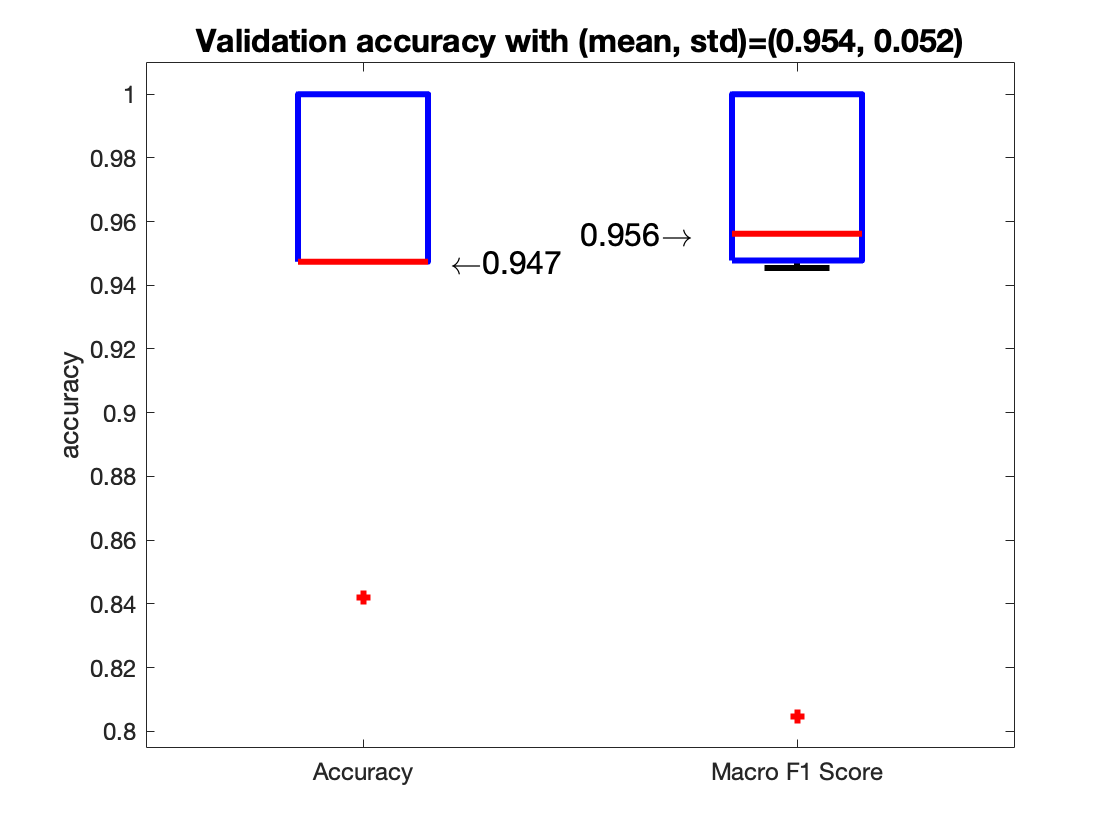


% plot validation accuracy from k-fold validation set
figure
h = boxplot([val_accs', val_f1s'], 'Labels', {'Accuracy','Macro F1 Score'});
text(1.2, median(val_accs),['\leftarrow', num2str(round(median(val_accs), 3))], 'FontSize', 16)
text(1.5, median(val_f1s),[num2str(round(median(val_f1s), 3)), '\rightarrow'], 'FontSize', 16)
ylabel('accuracy')
set(h,'LineWidth', 3)
set(gca,'FontSize',12)
title(['Validation accuracy with (mean, std)=(', num2str(round(mean(val_accs), 3)), ', ' num2str(round(std(val_accs), 3)), ')'], 'Fontsize', 16)

## EEG spectrum classification via SVM

**Task**: Predict sleep stage

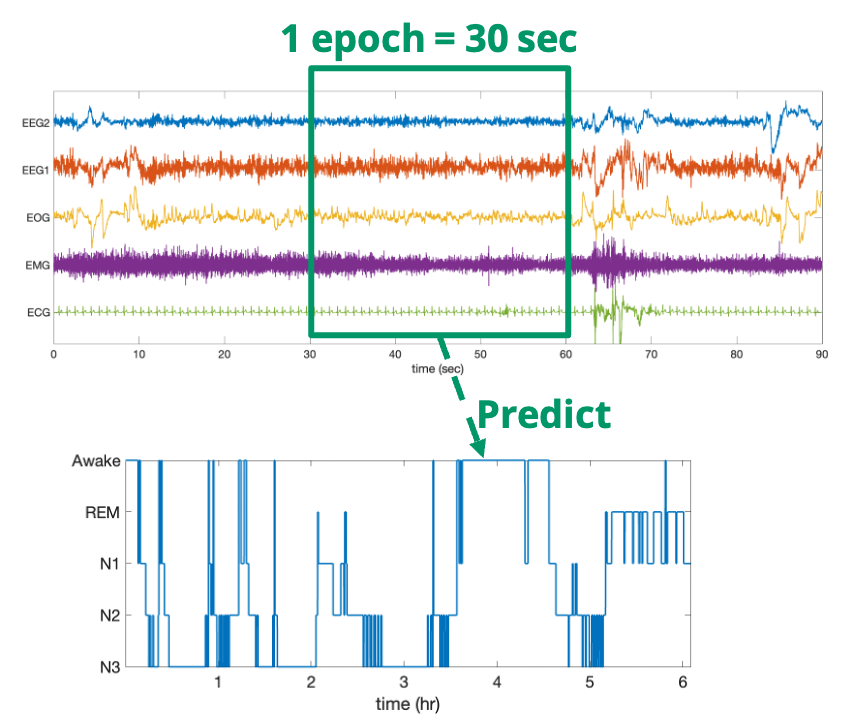

**Methodology**: Here, the EEG signals data are prepocessed by scattering transform

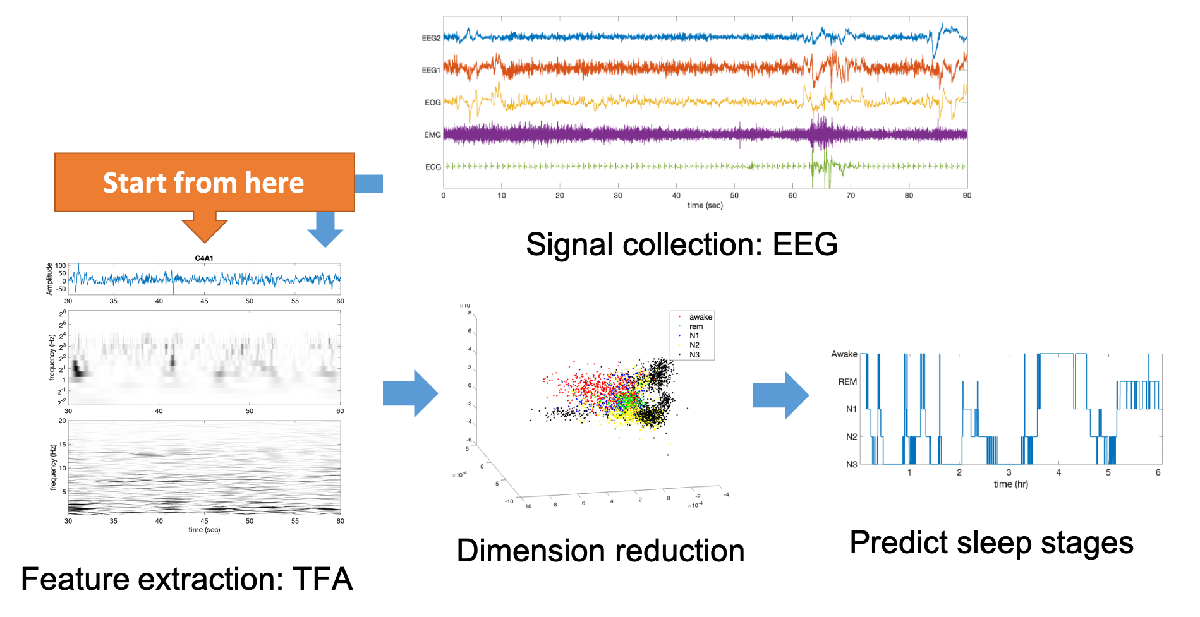

clc; clear; close all;
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
load("EEG_spectrum.mat")
n = size(X, 1);
Y_hot = zeros(n, 3);
for i = 1:5
    Y_hot(Y==i, i) = 1;
end

% Dimension reduction by DM
[U, S] = DMap4EEG(X, 30);

The kernel bandwidth is 21.6424.



% split train and validation set
train_ratio = 0.8;
[train_idx, val_idx] = Split_Set(n, train_ratio);

% SVM
template = templateSVM('KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], 'KernelScale', 10, ...
    'BoxConstraint', 1, 'Standardize', true);

model = fitcecoc(U(val_idx, :), Y(val_idx, :), ...
    'Learners', template, ...
     'Coding', 'onevsone', ...
     'ClassNames', [1; 2; 3; 4; 5]);
 
[~, train_scores] = predict(model, U(train_idx, :));
[~, conf_mat] = confusion(Y_hot(train_idx, :)', train_scores');

acc = sum(diag(conf_mat)) / sum(conf_mat(:));
disp(['Training accuracy = ' num2str(acc)])

Training accuracy = 0.84426



[~, val_scores] = predict(model, U(val_idx, :));
[~, conf_mat] = confusion(Y_hot(val_idx, :)', val_scores');

[cell_info, ~, ~, ~] = CM2Info(conf_mat, {'Aw', 'REM', 'N1', 'N2', 'N3'});
disp('The following is confusion matrix of validation set')

The following is confusion matrix of validation set


disp(cell_info)

  Columns 1 through 7

    {0×0 double        }    {'Predict-Aw'}    {'Predict-REM'}    {'Predict-N1'}    {'Predict-N2'}    {'Predict-N3'}    {'PR'      }
    {'Target-Aw (21%)' }    {'166 (89%)' }    {'10 (5%)'    }    {'7 (4%)'    }    {'3 (2%)'    }    {'0 (0%)'    }    {[  0.9326]}
    {'Target-REM (16%)'}    {'3 (2%)'    }    {'133 (96%)'  }    {'0 (0%)'    }    {'3 (2%)'    }    {'0 (0%)'    }    {[  0.8061]}
    {'Target-N1 (8%)'  }    {'8 (12%)'   }    {'15 (22%)'   }    {'32 (47%)'  }    {'13 (19%)'  }    {'0 (0%)'    }    {[  0.8205]}
    {'Target-N2 (41%)' }    {'1 (0%)'    }    {'7 (2%)'     }    {'0 (0%)'    }    {'356 (98%)' }    {'1 (0%)'    }    {[  0.9013]}
    {'Target-N3 (15%)' }    {'0 (0%)'    }    {'0 (0%)'     }    {'0 (0%)'    }    {'20 (15%)'  }    {'114 (85%)' }    {[  0.9913]}
    {0×0 double        }    {0×0 double  }    {0×0 double   }    {0×0 double  }    {0×0 double  }    {0×0 double  }    {0×0 double}
    {'Accuracy: 0.898' }    {0×0 double  }    {0×0 do